% Auto-generated by cameraCalibrator app on 25-Jul-2025
%-------------------------------------------------------

% Define images to process
imageFileNames = {'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal0_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal1_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal2_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal3_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal4_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal5_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal6_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal7_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal8_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal9_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal10_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal11_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal12_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal13_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal14_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal15_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal16_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal17_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal18_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal19_seg.png',...
    };
% Detect calibration pattern in images
detector = vision.calibration.monocular.CheckerboardDetector();
minCornerMetric = 0.120000;
[imagePoints, imagesUsed] = detectPatternPoints(detector, imageFileNames, 'MinCornerMetric', minCornerMetric, 'HighDistortion', true);

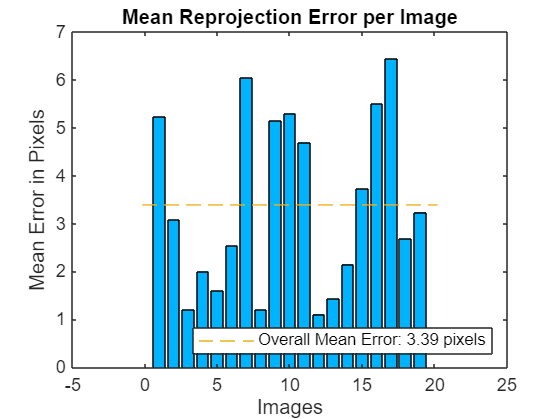

imageFileNames = imageFileNames(imagesUsed);

% Read the first image to obtain image size
originalImage = imread(imageFileNames{1});
[mrows, ncols, ~] = size(originalImage);

% Generate world coordinates for the planar pattern keypoints
squareSize = 25.000000;  % in millimeters
worldPoints = generateWorldPoints(detector, 'SquareSize', squareSize);

% Calibrate the camera
[cameraParams, imagesUsed, estimationErrors] = estimateCameraParameters(imagePoints, worldPoints, ...
    'EstimateSkew', false, 'EstimateTangentialDistortion', false, ...
    'NumRadialDistortionCoefficients', 2, 'WorldUnits', 'millimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [], ...
    'ImageSize', [mrows, ncols]);

% View reprojection errors
h1=figure; showReprojectionErrors(cameraParams);

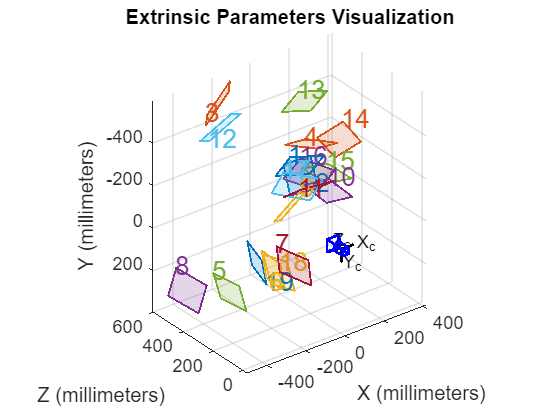


% Visualize pattern locations
h2=figure; showExtrinsics(cameraParams, 'CameraCentric');


% Display parameter estimation errors
displayErrors(estimationErrors, cameraParams);


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [  429.1339 +/- 6.7958      428.9629 +/- 6.8466  ]
Principal point (pixels):[  580.8487 +/- 1.7336      597.7439 +/- 1.2623  ]
Radial distortion:       [   -0.2980 +/- 0.0088        0.0501 +/- 0.0033  ]

Extrinsics
----------
Rotation vectors:
                         [    0.5007 +/- 0.0350        0.1095 +/- 0.0251        0.2589 +/- 0.0124  ]
                         [    0.1557 +/- 0.0231       -0.6547 +/- 0.0229       -2.9851 +/- 0.0095  ]
                         [    0.4983 +/- 0.0838       -0.3557 +/- 0.0817       -0.4920 +/- 0.0319  ]
                         [    0.9513 +/- 0.0540        0.2243 +/- 0.0458        0.3832 +/- 0.0189  ]
                         [   -0.9242 +/- 0.0786       -0.3580 +/- 0.0676        0.6119 +/- 0.0291  ]
                         [   -0.6500 +/- 0.0372       -0.8219 +/- 0.0339       -0.8801 +/- 0.0161  ]
 


% For example, you can use the calibration data to remove effects of lens distortion.
undistortedImage = undistortImage(originalImage, cameraParams);

% See additional examples of how to use the calibration data.  At the prompt type:
%showdemo('MeasuringPlanarObjectsExample')
%showdemo('StructureFromMotionExample')